# NMPC Final Project:

OCP :

a) Formulate at least two OCPs that drive the robot from the initial position q = (−5, −4)⊤ rad, q˙ = (0, 0)⊤ rad/s to the upper position q = ( π 2 , 0)⊤ rad, q˙ = (0, 0)⊤ rad/s in 3 s. Thereby, the input constraints u ∈ [−1000 1000]Nm and the state constraints q˙ ∈ [− 3 2 π 3 2 π] rad/s should be satisfied for all times. Motivate your problem formulation.

a.1) Quadratic Cost Function(input + state errors): + Terminal Constraint

close all; clear variables; clc
import casadi.*

% Lengths of the robot links:
l1= 0.5; % [m]
l2= 0.5; % [m]

% Sampling Time
Ts = 0.1; % [s]

% NMPC Time
Tmpc = 8; % [s]
Nmpc = Tmpc/Ts ; % [steps]
tmpc05 = 0:Ts:Tmpc; % [0......Tfinal]

% simulation time
t0      =   0; % start time [s]
Tfinal       =   10; % end time of simulation [s]
tsim    =   0:Ts:Tfinal; % [0......Tfinal]
ksim    =   length(tsim); % Num of steps

% initial and terminal states
x0   = [-5; 0; -4; 0]; % [q1 q_dot1 q2 q_dot2]
xend = [pi/2; 0; 0; 0]; % [q1 q_dot1 q2 q_dot2]

% get dimensions
nx = 4; % [q1 q_dot1 q2 q_dot2]
nu = 2; % [u1 u2]

% define weighting matrices (unit weigths)
Q = 1e2*diag([1 1 1 1]);
R = 1e-2*diag([3 1]); % Reduce more bec values of inputs (u1, u2) is much bigger than the states

% limits
xmax= [6; 3*pi/2; 6; 3*pi/2]; % [q1 q_dot1 q2 q_dot2]
xmin= -xmax; % [q1 q_dot1 q2 q_dot2]
umax= [1000; 1000]; % [u1 u2]
umin= -umax; % [u1 u2]

%% set up optimal control problem:
ocp = casadi.Opti();

% declare optimization variables
U = ocp.variable(nu,Nmpc);
X = ocp.variable(nx,Nmpc+1); % +1 than u bec there is only a state when terminal state is reached and no input
J = 0; % cost

% OCP Formulation Loop:
for i = 1:Nmpc
    % propagate state using Integrals:
    % Uncomment the needed Integral
    %         RK4:
         x_next  =   rk4(@(t,x,u)dynamicsfun(t,x,u),Ts,tmpc05(i),X(:,i),U(:,i));
    
    %   Euler Forward:
%     x_next = eulerf(@(t,x,u)dynamicsfun(t,x,u),Ts,tmpc(i),X(:,i),U(:,i));

    %   Heun Forward:
%     x_next = heun(@(t,x,u)dynamicsfun(t,x,u),Ts,tmpc(i),X(:,i),U(:,i));

    % add constraint
    ocp.subject_to(X(:,i+1) == x_next);

    % construct an objective
    J = J + (X(:,i+1) - xend)' * Q * (X(:,i+1) - xend) + U(:,i)' * R * U(:,i);
end

% initial constraint
X0      =   ocp.parameter(nx,1); % Used in MPC Loop when init state is changed
ocp.set_value(X0, x0) % Set init state
ocp.subject_to( X(:,1) == X0 ); % Initial State assigned to X opti variable

% terminal constraint
ocp.subject_to( X(:,end) == xend );

% path constraints
ocp.subject_to( xmin <= X <= xmax );
ocp.subject_to( umin <= U <= umax );

% add cost function
ocp.minimize(J);

% specify solver
ocp.solver('ipopt');

% solve OCP
sol = ocp.solve();


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2248
Number of nonzeros in inequality constraint Jacobian.:      484
Number of nonzeros in Lagrangian Hessian.............:     1690

Total number of variables............................:      484
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      328
Total number of inequality c

% Extract solutions
xSS_0_1 = sol.value(X);
uSS_0_1 = sol.value(U);

save('sol_0.1.mat', 'xSS_0_1', 'uSS_0_1');

load('sol_rk4.mat')

## Plotting different solvers answers and sampling points

% Load data from sol_rk4, sol_heu, and sol_eul
load('sol_0.05.mat');
load('sol_0.1.mat');
load('sol_0.5.mat');
clf;
% Create subplots
subplot(3, 3, 1);
xSS_rk4 = xSS_0_05;
xSS_heu = xSS_0_1;
xSS_eul =xSS_0_5;
uSS_rk4 = uSS_0_05;
uSS_heu = uSS_0_1;
uSS_eul =uSS_0_5;
tmpc005 = 0:0.05:Tmpc;
plot(tmpc005, xSS_rk4([1], :)', 'b-');
hold on;
plot(tmpc005, xSS_rk4([3], :)', 'b--');
tmpc01 = 0:0.1:Tmpc;
plot(tmpc01,xSS_heu([1], :)', 'r-');
plot(tmpc01,xSS_heu([3], :)', 'r--');
tmpc05 = 0:0.5:Tmpc;
plot(tmpc05,xSS_eul([1 3], :)','g-');
plot(tmpc05,xSS_eul([1 3], :)','g--');
grid on;
title('Angles (rad)');
xlabel('Time (s)');
ylabel('Angle (rad)');
legend('0.05 q1', '0.05 q2', '0.1 q1', '0.1 q2', '0.5 q1', '0.5 q2');

subplot(3, 3, 2);
plot(tmpc005,xSS_rk4([2], :)', 'b-');
hold on;
plot(tmpc005,xSS_rk4([4], :)', 'b--');
plot(tmpc01,xSS_heu([2], :)', 'r-');
plot(tmpc01,xSS_heu([4], :)', 'r--');
plot(tmpc05,xSS_eul([2], :)', 'g-');
plot(tmpc05,xSS_eul([4], :)', 'g--');
grid on;
hold on;
plot(tmpc,xmin(2)*ones(Nmpc+1,1),'y--');
plot(tmpc,xmax(2)*ones(Nmpc+1,1),'y--');
title('Velocities (rad/s)');
xlabel('Time (s)');
ylabel('Velocity (rad/s)');
legend('0.05 q1dot', '0.05 q2dot', '0.1 q1dot', '0.1 q2dot', '0.5 q1dot', '0.5 q2dot');
subplot(3,3,3);
plot(tmpc005(1:end-1),uSS_rk4([1], :)','b-');
hold on;
plot(tmpc005(1:end-1),uSS_rk4([2], :)','b--');
plot(tmpc01(1:end-1),uSS_heu([1], :)','r-');
plot(tmpc01(1:end-1),uSS_heu([2], :)','r--');
plot(tmpc05(1:end-1),uSS_eul([1], :)','g-');
plot(tmpc05(1:end-1),uSS_eul([2], :)','g--');
grid on;
plot(tmpc(1:end-1),umin(1)*ones(Nmpc,1),'--y')
plot(tmpc(1:end-1),umax(1)*ones(Nmpc,1),'--y')
title('Controls (Nm)');
xlabel('Time (s)');
ylabel('Control (Nm)');
legend('0.05 u1', '0.05 u2', '0.1 u1','0.1 u2', '0.5 u1', '0.5 u2', 'Control limits');

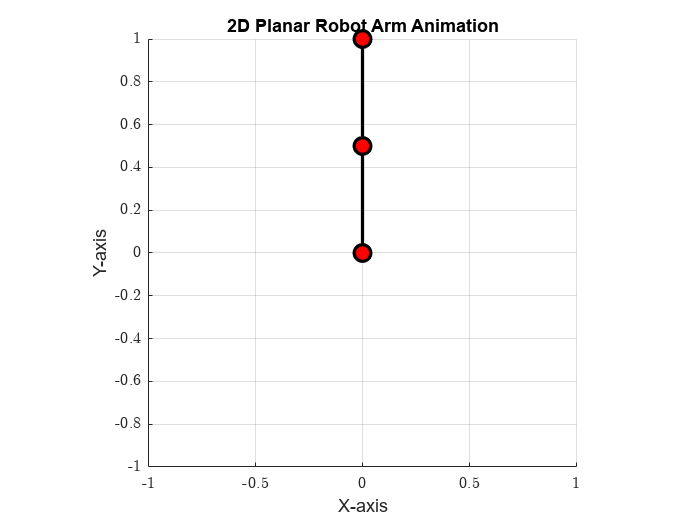

% % Animate the robot arm
animate_robot_arm(q1, q2);

With terminal penalty

close all; clear variables; clc
import casadi.*

% Lengths of the robot links:
l1= 0.5; % [m]
l2= 0.5; % [m]

% Sampling Time
Ts = 0.05; % [s]

% NMPC Time
Nmpc = 100; % [steps]
Tmpc = Nmpc*Ts; % [s]
tmpc05 = 0:Ts:Tmpc; % [0......Tfinal]

% simulation time
t0      =   0; % start time [s]
Tfinal       =   5; % end time of simulation [s]
tsim    =   0:Ts:Tfinal; % [0......Tfinal]
ksim    =   length(tsim); % Num of steps

% initial and terminal states
x0   = [-5; 0; -4; 0]; % [q1 q_dot1 q2 q_dot2]
xend = [pi/2; 0; 0; 0]; % [q1 q_dot1 q2 q_dot2]

% get dimensions
nx = 4; % [q1 q_dot1 q2 q_dot2]
nu = 2; % [u1 u2]

% define weighting matrices (unit weigths)
Q = 1e2*diag([1 1 1 1]);
R = diag([3 1]); % Reduce more bec values of inputs (u1, u2) is much bigger than the states

% limits
xmax= [6; 3*pi/2; 6; 3*pi/2]; % [q1 q_dot1 q2 q_dot2]
xmin= -xmax; % [q1 q_dot1 q2 q_dot2]
umax= [1000; 1000]; % [u1 u2]
umin= -umax; % [u1 u2]

%% set up optimal control problem:
ocp = casadi.Opti();

% declare optimization variables
U = ocp.variable(nu,Nmpc);
X = ocp.variable(nx,Nmpc+1); % +1 than u bec there is only a state when terminal state is reached and no input
J = 0; % cost

% OCP Formulation Loop:
for i = 1:Nmpc
    % propagate state using Integrals:
    % Uncomment the needed Integral
    %         RK4:
         x_next  =   rk4(@(t,x,u)dynamicsfun(t,x,u),Ts,tmpc05(i),X(:,i),U(:,i));
    
    %   Euler Forward:
%     x_next = eulerf(@(t,x,u)dynamicsfun(t,x,u),Ts,tmpc(i),X(:,i),U(:,i));

    %   Heun Forward:
%     x_next = heun(@(t,x,u)dynamicsfun(t,x,u),Ts,tmpc(i),X(:,i),U(:,i));

    % add constraint
    ocp.subject_to(X(:,i+1) == x_next);

    % construct an objective
    J = J + (X(:,i+1) - xend)' * Q * (X(:,i+1) - xend) + U(:,i)' * R * U(:,i);
end

% initial constraint
X0      =   ocp.parameter(nx,1); % Used in MPC Loop when init state is changed
ocp.set_value(X0, x0) % Set init state
ocp.subject_to( X(:,1) == X0 ); % Initial State assigned to X opti variable

% terminal constraint - Here No Terminal Constraint => Terminal Cost
% ocp.subject_to( X(:,end) == xend );
beta = 50000; % Large penalised Parameter
J = J + beta * (X(:,end) - xend)'*(X(:,end) - xend);

% path constraints
ocp.subject_to( xmin <= X <= xmax );
ocp.subject_to( umin <= U <= umax );

% add cost function
ocp.minimize(J);

% specify solver
ocp.solver('ipopt');

% solve OCP
sol = ocp.solve();


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2804
Number of nonzeros in inequality constraint Jacobian.:      604
Number of nonzeros in Lagrangian Hessian.............:     2110

Total number of variables............................:      604
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality c

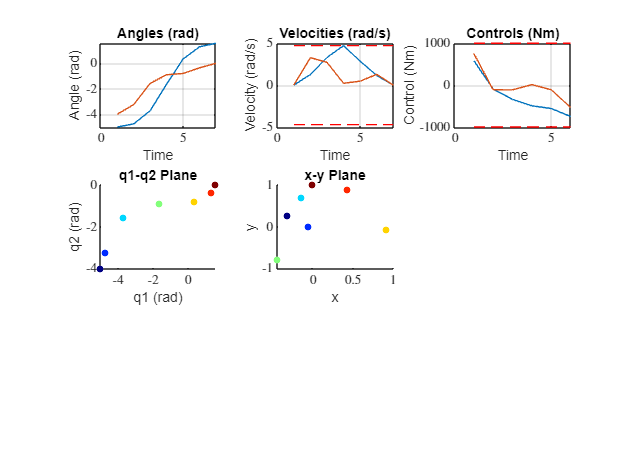

% Extract solutions
xSS = sol.value(X);
uSS = sol.value(U);

% Plots
subplot(3,3,1);
plot(sol.value(X([1 3],:))');
grid on;
hold on;
title('Angles (rad)');
xlabel('Time');
ylabel('Angle (rad)');
subplot(3,3,2);
plot(sol.value(X([2 4],:))')
grid on;
hold on;
plot(1:Nmpc+1,xmin(2)*ones(Nmpc+1,1),'--r');
plot(1:Nmpc+1,xmax(2)*ones(Nmpc+1,1),'--r');
title('Velocities (rad/s)');
xlabel('Time');
ylabel('Velocity (rad/s)');
subplot(3,3,3);
plot(sol.value(U)')
grid on;
hold on;
plot(1:Nmpc,umin(1)*ones(Nmpc,1),'--r')
plot(1:Nmpc,umax(1)*ones(Nmpc,1),'--r')
title('Controls (Nm)');
xlabel('Time');
ylabel('Control (Nm)');
subplot(3,3,4);
% Plot in q1-q2 Plane
q1 = sol.value(X([1],:));
q2 = sol.value(X([3],:));
c = linspace(1, 10, length(q1));  % You can use any variable for gradient color
scatter(q1, q2, 20, c, 'filled')
title('q1-q2 Plane');
xlabel('q1 (rad)');
ylabel('q2 (rad)');
subplot(3,3,5);
% Plot in x-y Plane
x = l1*cos(q1) + l2* cos(q1+q2);
y = l1*sin(q1) + l2* sin(q1+q2);
c = linspace(1, 10, length(x));  % You can use any variable for gradient color
scatter(x, y, 20, c, 'filled')
colormap('jet'); % You can choose other colormaps, e.g., 'parula', 'hot', etc.
title('x-y Plane');
xlabel('x');
ylabel('y');

## MPC LOOP:

[fx, fu, xeco, ueco] = MPCloop(U,X,X0,ocp,@(t,x,u)dynamicsfun_mismatch(t,x,u),Ts,6,[-5; 0; -4; 0],[0; 0]);

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     1688
Number of nonzeros in inequality constraint Jacobian.:      364
Number of nonzeros in Lagrangian Hessian.............:     1270

Total number of variables............................:      364
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      248
Total number of inequality constraints...............:      364
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:      364
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  3.5505219e+05 6.57e+00 1.00e+02  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

xSS = sol.value(X);
uSS = sol.value(U);

## Calculating and plotting the open loop response of mismatched model

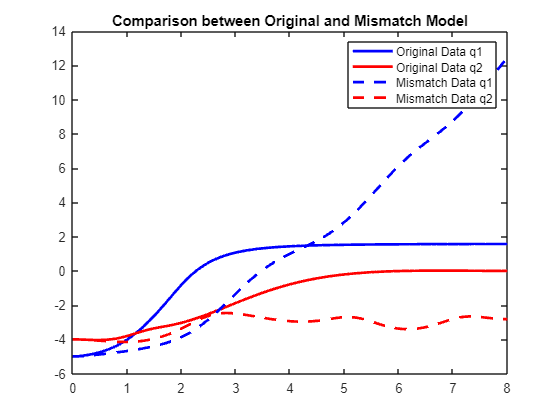

% Draw the Open LooP:
Usol = sol.value(U);
x =   zeros(nx,Nmpc+1);
x_mismatch =   zeros(nx,Nmpc+1);
u =   zeros(nu,Nmpc);
x(:,1)  =   x0;
x_mismatch(:,1) =   x0;
for k = 1:Nmpc
    % get first element
    % apply to system using rk4
    x(:,k+1) =   rk4(@(t,x,u)dynamicsfun(t,x,u),Ts,0,x(:,k),Usol(:,k));
    x_mismatch(:,k+1) =   rk4(@(t,x,u)dynamicsfun_mismatch(t,x,u),Ts,0,x_mismatch(:,k),Usol(:,k));
end
figure;

% Plot the first component of the original data
plot(tmpc05, x(1,:), 'LineWidth', 2, 'Color', 'b');
hold on;

% Plot the second component of the original data
plot(tmpc05, x(3,:), 'LineWidth', 2, 'Color', 'r');

% Plot the first component of the mismatch data with dashed line
plot(tmpc05, x_mismatch(1,:), '--', 'LineWidth', 2, 'Color', 'b');

% Plot the second component of the mismatch data with dashed line
plot(tmpc05, x_mismatch(3,:), '--', 'LineWidth', 2, 'Color', 'r');

hold off;

% Add legend
legend('Original Data q1', 'Original Data q2', 'Mismatch Data q1', 'Mismatch Data q2');

% Add title
title('Comparison between Original and Mismatch Model');

## Comparison Between Open and Closed loop with mismatched model using MPC:

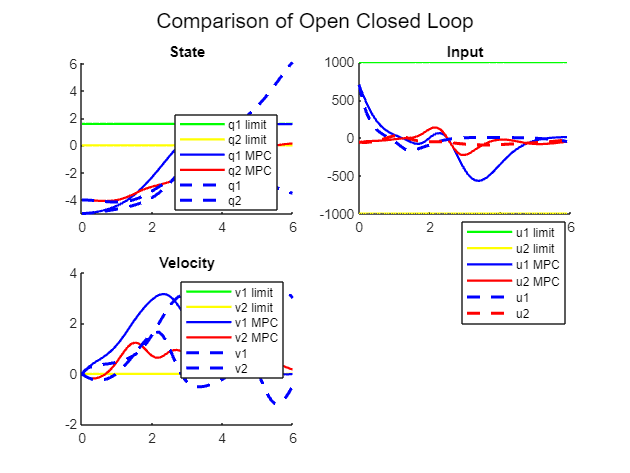

% Solution from the MPC loop
Leco2    =   xeco(end,:);
xeco2    =   xeco(1:nx,:);
%plotresults(tmpc,xeco2,ueco,xSS,uSS,[14,15]);
linewidth = 1.5;
% q1 Setpoint
figure
sgtitle('Comparison of Open Closed Loop');
subplot(2,2,1)
hold on
% Plot NMPC Output
plot(tmpc05,xend(1)*ones(size(tmpc05)),'LineWidth',linewidth, 'Color','g');
plot(tmpc05,xend(3)*ones(size(tmpc05)),'Linewidth',linewidth, 'Color','y');
plot(tmpc05,xeco2(1,:),'Linewidth',linewidth, 'Color','b');
plot(tmpc05,xeco2(3,:),'Linewidth',linewidth, 'Color','r');
% Plot the first component of the mismatch data with dashed line
plot(tmpc05, x_mismatch(1,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot Open Loop Output [from OCP solution before NMPC Loop]
% plot(tmpc05, xSS(1,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the second component of the original data
% Plot the first component of the mismatch data with dashed line
plot(tmpc05, x_mismatch(3,:), '--', 'LineWidth', 2, 'Color', 'b');
% plot(tmpc05, xSS(3,:), '--', 'LineWidth', 2, 'Color', 'r');
hold off
title('State')
legend('q1 limit','q2 limit','q1 MPC','q2 MPC', 'q1', 'q2')

subplot(2,2,2)
hold on
plot(tmpc05(1:end-1),umax(1)*ones(size(tmpc05(1:end-1))),'LineWidth',linewidth, 'Color','g');
plot(tmpc05(1:end-1),umin(1)*ones(size(tmpc05(1:end-1))),'Linewidth',linewidth, 'Color','y');

plot(tmpc05(1:end-1),ueco(1,:),'Linewidth',linewidth, 'Color','b');
plot(tmpc05(1:end-1),ueco(2,:),'Linewidth',linewidth, 'Color','r');

% Plot Open Loop Output [from OCP solution before NMPC Loop]
plot(tmpc05(1:end-1), uSS(1,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the second component of the original data
plot(tmpc05(1:end-1), uSS(2,:), '--', 'LineWidth', 2, 'Color', 'r');
hold off
title('Input')
legend('u1 limit','u2 limit','u1 MPC','u2 MPC', 'u1', 'u2')

subplot(2,2,3)
hold on
plot(tmpc05,xend(2)*ones(size(tmpc05)),'LineWidth',linewidth, 'Color','g');
plot(tmpc05,xend(4)*ones(size(tmpc05)),'Linewidth',linewidth, 'Color','y');

plot(tmpc05,xeco2(2,:),'Linewidth',linewidth, 'Color','b');
plot(tmpc05,xeco2(4,:),'Linewidth',linewidth, 'Color','r');

% Plot Open Loop Output [from OCP solution before NMPC Loop]
% plot(tmpc05, xSS(2,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the second component of the original data
% plot(tmpc05, xSS(4,:), '--', 'LineWidth', 2, 'Color', 'r');
% Plot the first component of the mismatch data with dashed line
plot(tmpc05, x_mismatch(2,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the first component of the mismatch data with dashed line
plot(tmpc05, x_mismatch(4,:), '--', 'LineWidth', 2, 'Color', 'b');
hold off
title('Velocity')
legend('v1 limit','v2 limit','v1 MPC','v2 MPC', 'v1', 'v2')

subplot(2,2,1)
legend("Position", [0.28092,0.58912,0.15696,0.13652])

subplot(2,2,2)
legend("Position", [0.73497,0.3166,0.1625,0.21548])

# MPC with Gaussain Noise

[fx, fu, xeco, ueco] = MPCloop(U,X,X0,ocp,@(t,x,u)dynamicsfun_mismatch(t,x,u),Ts,Tfinal,[-5; 0; -4; 0],[0; 0]);

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2248
Number of nonzeros in inequality constraint Jacobian.:      484
Number of nonzeros in Lagrangian Hessian.............:     1690

Total number of variables............................:      484
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      328
Total number of inequality constraints...............:      484
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:      484
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  4.7340291e+05 6.57e+00 1.00e+02  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

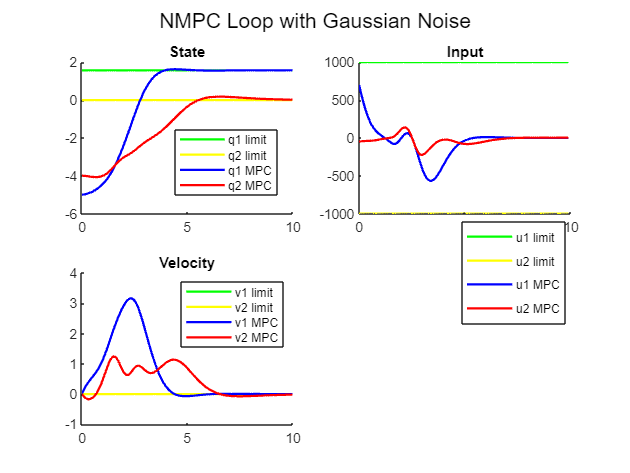

% Solution from the MPC loop
Leco2    =   xeco(end,:);
xeco2    =   xeco(1:nx,:);
%plotresults(tmpc,xeco2,ueco,xSS,uSS,[14,15]);
linewidth = 1.5;
% q1 Setpoint
figure
sgtitle('NMPC Loop with Gaussian Noise');
subplot(2,2,1)
hold on
% Plot NMPC Output
plot(tmpc05,xend(1)*ones(size(tmpc05)),'LineWidth',linewidth, 'Color','g');
plot(tmpc05,xend(3)*ones(size(tmpc05)),'Linewidth',linewidth, 'Color','y');
plot(tmpc05,xeco2(1,:),'Linewidth',linewidth, 'Color','b');
plot(tmpc05,xeco2(3,:),'Linewidth',linewidth, 'Color','r');
% Plot the first component of the mismatch data with dashed line
% plot(tmpc05, x_mismatch(1,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot Open Loop Output [from OCP solution before NMPC Loop]
% plot(tmpc05, xSS(1,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the second component of the original data
% Plot the first component of the mismatch data with dashed line
% plot(tmpc05, x_mismatch(3,:), '--', 'LineWidth', 2, 'Color', 'b');
% plot(tmpc05, xSS(3,:), '--', 'LineWidth', 2, 'Color', 'r');
hold off
title('State')
legend('q1 limit','q2 limit','q1 MPC','q2 MPC')

subplot(2,2,2)
hold on
plot(tmpc05(1:end-1),umax(1)*ones(size(tmpc05(1:end-1))),'LineWidth',linewidth, 'Color','g');
plot(tmpc05(1:end-1),umin(1)*ones(size(tmpc05(1:end-1))),'Linewidth',linewidth, 'Color','y');

plot(tmpc05(1:end-1),ueco(1,:),'Linewidth',linewidth, 'Color','b');
plot(tmpc05(1:end-1),ueco(2,:),'Linewidth',linewidth, 'Color','r');

% Plot Open Loop Output [from OCP solution before NMPC Loop]
% plot(tmpc05(1:end-1), uSS(1,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the second component of the original data
% plot(tmpc05(1:end-1), uSS(2,:), '--', 'LineWidth', 2, 'Color', 'r');
hold off
title('Input')
legend('u1 limit','u2 limit','u1 MPC','u2 MPC')

subplot(2,2,3)
hold on
plot(tmpc05,xend(2)*ones(size(tmpc05)),'LineWidth',linewidth, 'Color','g');
plot(tmpc05,xend(4)*ones(size(tmpc05)),'Linewidth',linewidth, 'Color','y');

plot(tmpc05,xeco2(2,:),'Linewidth',linewidth, 'Color','b');
plot(tmpc05,xeco2(4,:),'Linewidth',linewidth, 'Color','r');

% Plot Open Loop Output [from OCP solution before NMPC Loop]
% plot(tmpc05, xSS(2,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the second component of the original data
% plot(tmpc05, xSS(4,:), '--', 'LineWidth', 2, 'Color', 'r');
% Plot the first component of the mismatch data with dashed line
% plot(tmpc05, x_mismatch(2,:), '--', 'LineWidth', 2, 'Color', 'b');
% Plot the first component of the mismatch data with dashed line
% plot(tmpc05, x_mismatch(4,:), '--', 'LineWidth', 2, 'Color', 'b');
hold off
title('Velocity')
legend('v1 limit','v2 limit','v1 MPC','v2 MPC')

subplot(2,2,1)
legend("Position", [0.28092,0.58912,0.15696,0.13652])

subplot(2,2,2)
legend("Position", [0.73497,0.3166,0.1625,0.21548])

# **OCP : Free End Time**

close all; clear variables; clc
import casadi.*

% Lengths of the robot links:
l1= 0.5; % [m]
l2= 0.5; % [m]

% NMPC Time
Nmpc = 200; % [steps] % num of control intervals

% initial and terminal states
x0   = [-5; 0; -4; 0]; % [q1 q_dot1 q2 q_dot2]
xend = [pi/2; 0; 0; 0]; % [q1 q_dot1 q2 q_dot2]

% get dimensions
nx = 4; % [q1 q_dot1 q2 q_dot2]
nu = 2; % [u1 u2]

% define weighting matrices (unit weigths)
% Q = 1e2*diag([1 1 1 1]);
R = 1e-3*diag([3 1]); % Reduce more bec values of inputs (u1, u2) is much bigger than the states

% limits
xmax= [6; 3*pi/2; 6; 3*pi/2]; % [q1 q_dot1 q2 q_dot2]
xmin= -xmax; % [q1 q_dot1 q2 q_dot2]
umax= [1000; 1000]; % [u1 u2]
umin= -umax; % [u1 u2]

%% set up optimal control problem:
ocp = casadi.Opti();

% declare optimization variables
U = ocp.variable(nu,Nmpc);
X = ocp.variable(nx,Nmpc+1); % +1 than u bec there is only a state when terminal state is reached and no input
J = 0; % cost

% Free end time variable
Tfinal= ocp.variable();

% length of a control interval [Resolution]
Ts= Tfinal/Nmpc;

% OCP Formulation Loop:
for i = 1:Nmpc
    % propagate state using Integrals:
    % Uncomment the needed Integral
    % RK4:
    x_next  =   rk4(@(t,x,u)dynamicsfun(t,x,u),Ts,0,X(:,i),U(:,i));

    % add constraint
    ocp.subject_to(X(:,i+1) == x_next);

    % construct an objective
    %J = J + U(:,i)' * R * U(:,i);
end

% initial constraint
X0      =   ocp.parameter(nx,1); % Used in MPC Loop when init state is changed
ocp.set_value(X0, x0) % Set init state
ocp.subject_to( X(:,1) == X0 ); % Initial State assigned to X opti variable

% terminal constraint
ocp.subject_to( X(:,end) == xend );

% path constraints
ocp.subject_to( xmin <= X <= xmax );
ocp.subject_to( umin <= U <= umax );

% Time Constraints
ocp.subject_to(Tfinal>=0);
ocp.set_initial(Tfinal, 1);

% add cost function
ocp.minimize(Tfinal); % Only min time
%ocp.minimize(J + 10000000 * Tfinal); % min time + control energy

% specify solver
ocp.solver('ipopt');

% solve OCP
sol = ocp.solve();

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     6408
Number of nonzeros in inequality constraint Jacobian.:     1205
Number of nonzeros in Lagrangian Hessian.............:     5401

Total number of variables............................:     1205
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      808
Total number of inequality constraints...............:     1205
        inequality constraints with only lower bounds:        1
   inequality constraints with lower and upper bounds:     1204
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  1.0000000e+00 5.00e+00 0.00e+00  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

clf;
% Plots
subplot(3,3,1);
plot(tmpc, xSS([1 3],:)');
grid on;
hold on;
title('Angles (rad)');
xlabel('Time (s)');
ylabel('Angle (rad)');
legend('q1', 'q2');
subplot(3,3,2);
plot(tmpc, xSS([2 4],:)');
grid on;
hold on;
plot(tmpc,xmin(2)*ones(Nmpc+1,1),'--r');
plot(tmpc,xmax(2)*ones(Nmpc+1,1),'--r');
title('Velocities (rad/s)');
xlabel('Time (s)');
ylabel('Velocity (rad/s)');
legend('dq1', 'dq2', 'Velocity limits');
subplot(3,3,3);
plot(tmpc(1:end-1), uSS([1 2],:)');
grid on;
hold on;
plot(tmpc(1:end-1),umin(1)*ones(Nmpc,1),'--r')
plot(tmpc(1:end-1),umax(1)*ones(Nmpc,1),'--r')
title('Controls (Nm)');
xlabel('Time (s)');
ylabel('Control (Nm)');
legend('u1', 'u2', 'Control limits');
subplot(3,3,4);
% Plot in q1-q2 Plane
q1 = sol.value(X([1],:));
q2 = sol.value(X([3],:));
c = linspace(1, 10, length(q1));  % You can use any variable for gradient color
scatter(q1, q2, 20, c, 'filled')
title('q1-q2 Plane');
xlabel('q1 (rad)');
ylabel('q2 (rad)');
subplot(3,3,5);
% Plot in x-y Plane
x = l1*cos(q1) + l2* cos(q1+q2);
y = l1*sin(q1) + l2* sin(q1+q2);
c = linspace(1, 10, length(x));  % You can use any variable for gradient color
scatter(x, y, 20, c, 'filled')
colormap('jet'); % You can choose other colormaps, e.g., 'parula', 'hot', etc.
title('x-y Plane');

% Extract solutions
xSS = sol.value(X);
uSS = sol.value(U);
t_min = sol.value(Tfinal)

t_min = 2.3631

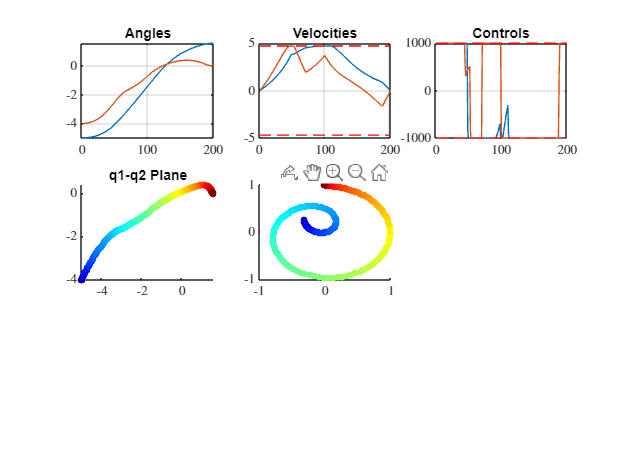

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2804
Number of nonzeros in inequality constraint Jacobian.:      604
Number of nonzeros in Lagrangian Hessian.............:     2110

Total number of variables............................:      604
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:      604
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:      604
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  2.4674011e+04 5.00e+00 1.00e+02  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2804
Number of nonzeros in inequality constraint Jacobian.:      604
Number of nonzeros in Lagrangian Hessian.............:     2110

Total number of variables............................:      604
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      404
Total number of inequality constraints...............:      604
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:      604
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  5.9175364e+05 2.26e-01 1.00e+02  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

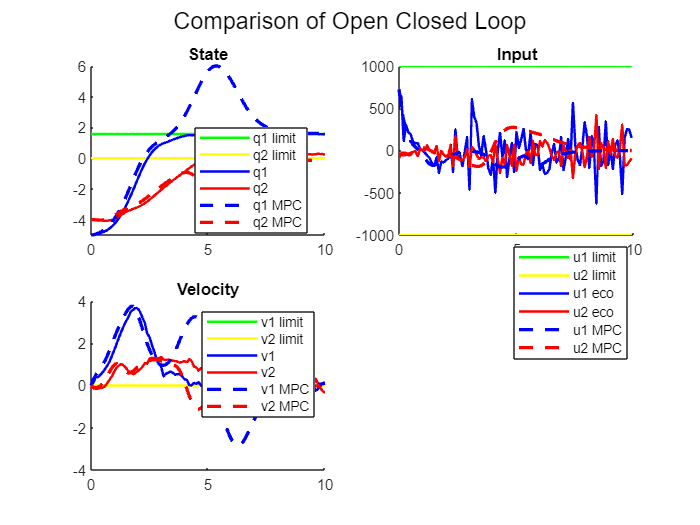

% Plots
subplot(3,3,1);
plot(sol.value(X([1 3],:))');
grid on;
hold on;
title('Angles');
subplot(3,3,2);
plot(sol.value(X([2 4],:))')
grid on;
hold on;
plot(1:Nmpc+1,xmin(2)*ones(Nmpc+1,1),'--r');
plot(1:Nmpc+1,xmax(2)*ones(Nmpc+1,1),'--r');
title('Velocities');
subplot(3,3,3);
plot(sol.value(U)')
grid on;
hold on;
plot(1:Nmpc,umin(1)*ones(Nmpc,1),'--r')
plot(1:Nmpc,umax(1)*ones(Nmpc,1),'--r')
title('Controls');
subplot(3,3,4);
% Plot in  q1-q2 Plane
q1 = sol.value(X([1],:));
q2 = sol.value(X([3],:));
c = linspace(1, 10, length(q1));  % You can use any variable for gradient color
scatter(q1, q2, 20, c, 'filled')
title('q1-q2 Plane');
subplot(3,3,5);
% Plot in  x-y Plane
x = l1*cos(q1) + l2* cos(q1+q2);
y = l1*sin(q1) + l2* sin(q1+q2);
c = linspace(1, 10, length(x));  % You can use any variable for gradient color
scatter(x, y, 20, c, 'filled')
colormap('jet'); % You can choose other colormaps, e.g., 'parula', 'hot', etc.
title('x-y Plane');

function animate_robot_arm(q1, q2)
    % Link lengths
    l1 = 0.5; % Length of the first link
    l2 = 0.5; % Length of the second link

    % Create a figure
    figure;
    axis equal;
    grid on;
    title('2D Planar Robot Arm Animation');
    xlabel('X-axis');
    ylabel('Y-axis');
    hold on;

    % Initialize animated line
    arm_line = animatedline('LineWidth', 2, 'Marker', 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

    % Set axis limits based on the link lengths
    axis([-l1-l2, l1+l2, -l1-l2, l1+l2]);

    % Animate the robot arm
    for i = 1:length(q1)
        % Forward kinematics
        x = [0, l1*cos(q1(i)), l1*cos(q1(i)) + l2*cos(q1(i) + q2(i))];
        y = [0, l1*sin(q1(i)), l1*sin(q1(i)) + l2*sin(q1(i) + q2(i))];

        % Update animated line
        clearpoints(arm_line);
        addpoints(arm_line, x, y);

        drawnow;
        pause(0.1); % Adjust the pause duration as needed
    end
end